# Plotting Gravitational Bodies (Circles)

We'll represent the game pieces using basic shapes, such as circles for the gravitational bodies (planets, moons, or stars).

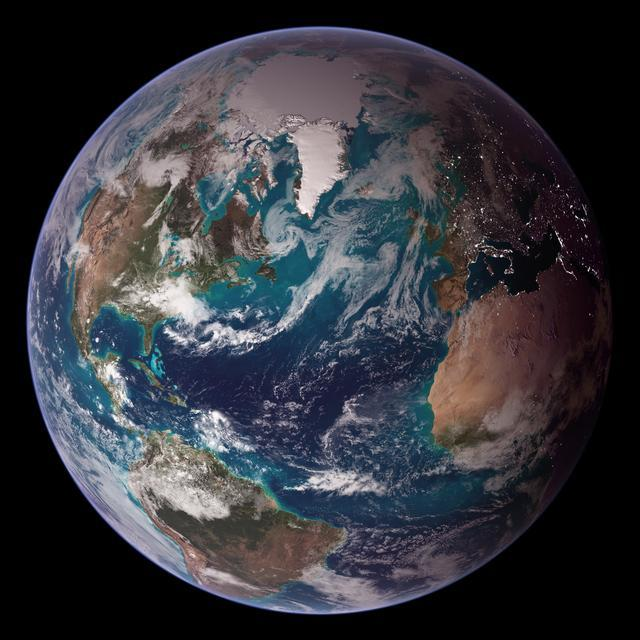     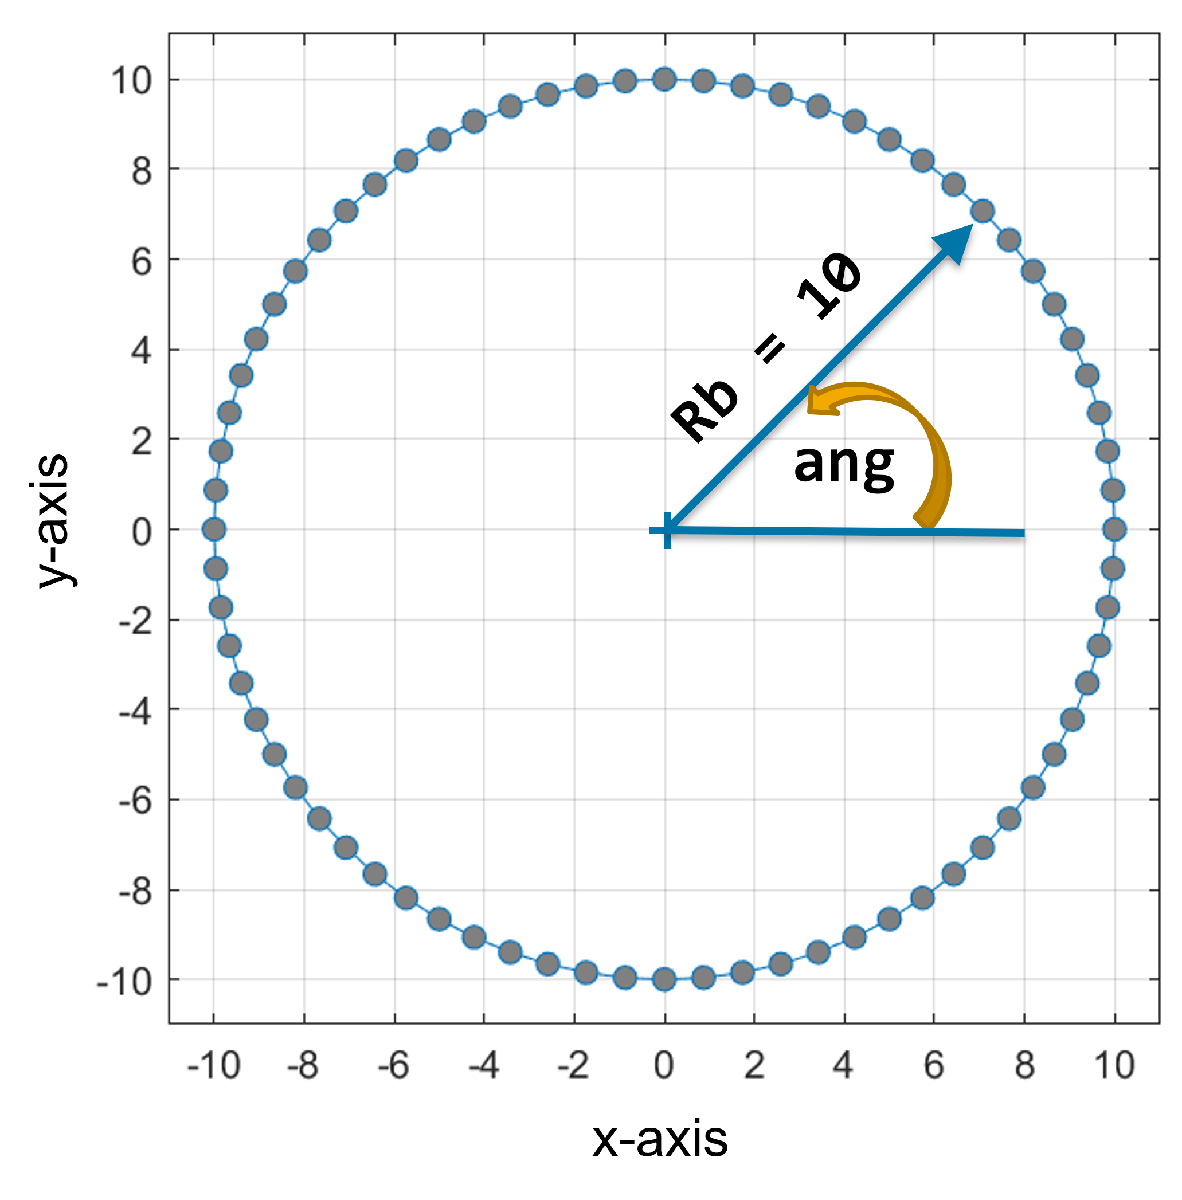

*Image Credit: *[*NASA Blue Marble 2007 West*](https://images.nasa.gov/details-GSFC_20171208_Archive_e002131)

To create a circle we'll need to specify the "x" (horizontal) and "y" (vertical) locations of the points on the circle.

## Plotting a Circle (Tasks 1 & 2)

Later when we create our Astro Volley App, our plotting commands will need to specify the target axes where we want our plot to be displayed.  We’ll practice this here by getting the current axes (`ax`) and using it as the first input with all of our plotting commands below.

ax = gca;  % get current axes
cla(ax)    % clear axes

To create the circle above we'd need to specify 73 x-values (`xc`) and 73 y-values (`yc`)!  Fortunately, there's a way we can do this without manually setting all 146 values.  Instead, we can just specify the angle values along the circle (`ang`) and the desired radius of the circle (`Rb`).

Recall we can create an array using colons as follows,

For example, the command below creates an array named `ang` with values from 0 to 360 in steps of 90 degrees.  (There are 360 degrees in a circle.)

% TASK 1: Change the step increment (between the colons) to something
% smaller until your circle becomes round like the illustration above.
ang = 0:90:360;       % angle, degrees

% TASK 2: Change the value of Rb to match the illustration above.
Rb = 1;               % circle radius (body size)

We can then use the cosine function (`cosd`) to generate the x-values and the sine function (`sind`) to generate the y-values.  Don't worry if you've never heard of these functions.  You'll learn more about them when you get to trigonometry later in your math studies.  (This part has already been completed in the code below.)

% Plot x and y circle values
xc = cosd(ang);       % unit circle x-points
yc = sind(ang);       % unit circle y-points
plot(ax,Rb*xc,Rb*yc)  % scale unit values by radius
axis(ax,"equal")      % so circle doesn't look stretched
xlim(ax,[-11 11])     % x-axis display limits [min max]
ylim(ax,[-11 11])     % y-axis display limits [min max]

We used the `xlim` and `ylim` functions to set the display limits on the x and y axes to match the figure above.  As such, if `Rb` is set larger than the circle radius illustrated above, your circle may not be visible inside the axes limits.

## Coloring the Body (Task 3)

We can fill our gravitational body with color by replacing the `plot` command with the `fill` command.  To do so we'll also need to specify the desired Red-Green-Blue [(RGB) color code](https://www.rapidtables.com/web/color/RGB_Color.html#color-table), which recall is an array of 3 numbers with values between 0 and 255.

For example, [255 255 0] represent a color with full red, full green, and no blue - which creates yellow.  (Hint: reduce the amount of green to create orange.)  Note, the `fill` function expects these values to be between 0 and 1, so we divide the color array by 255.  This has already been added to the code below.

% TASK 3: Change the zeros in the color code below
% to create a red/orange body (instead of black).
cb = [0 0 0]/255;  % body RGB color code

% Plot body filled with color
fill(ax,Rb*xc,Rb*yc,cb)
axis(ax,"equal")

Notice that if we do not specify x and y axes limits, MATLAB automatically zooms in on the plot; but we can still see the circle size based on the x-axis and y-axis labels.

## Relocating the Body (Task 4)

We can relocate the body from (0,0) to another position by specifying the x and y values of the new location and adding these to the x and y values of the circle.

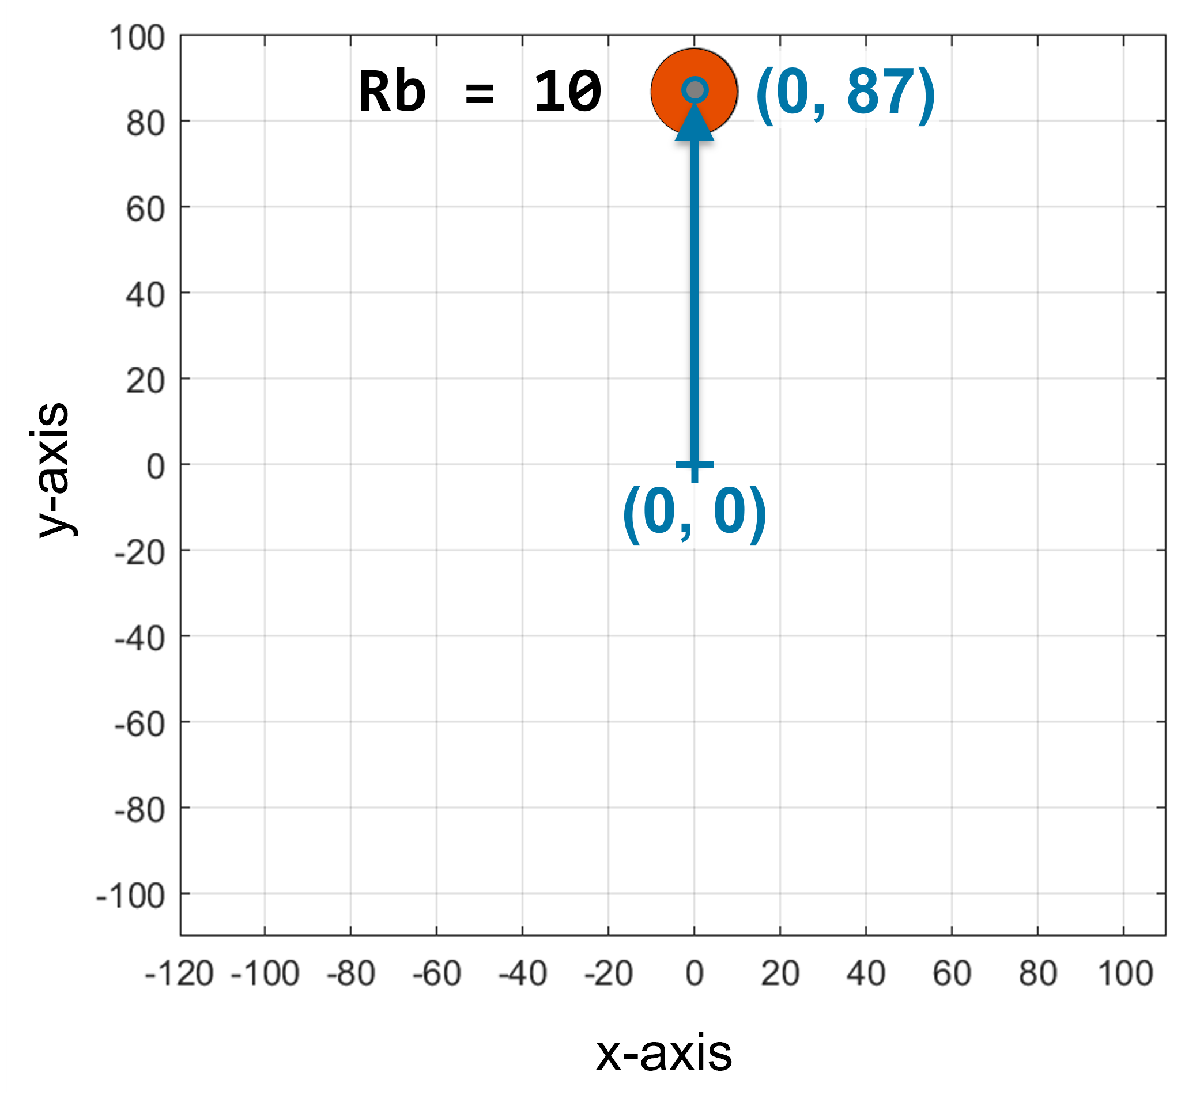

% TASK 4: Change the values of xb and yb to relocate the
% body to the x and y location illustrated above.
xb = 0;  % body x-position
yb = 0;  % body y-position

% Plot relocated body filled with color
fill(ax,xb+Rb*xc,yb+Rb*yc,cb)
axis(ax,"equal")
xlim(ax,[-120 110])  % x-axis display limits [min max]
ylim(ax,[-100 100])  % y-axis display limits [min max]

Once again we used the `xlim` and `ylim` functions to set the display limits on the x and y axes to match the figure above.  As such, if `xb` and `yb` are not set to match the body position illustrated above, your gravitational body may not be visible inside the axes limits.

## Adding Additional Bodies (Tasks 5, 6, & 7)

We can add more bodies by adding additional values to our variables for the body x location (`xb`), y location (`yb`), size (`Rb`), and color code (`cb`).  We'll then use the first value of each array to plot Body 1; the second value of each array to plot Body 2; and the third value of each array to plot Body 3.

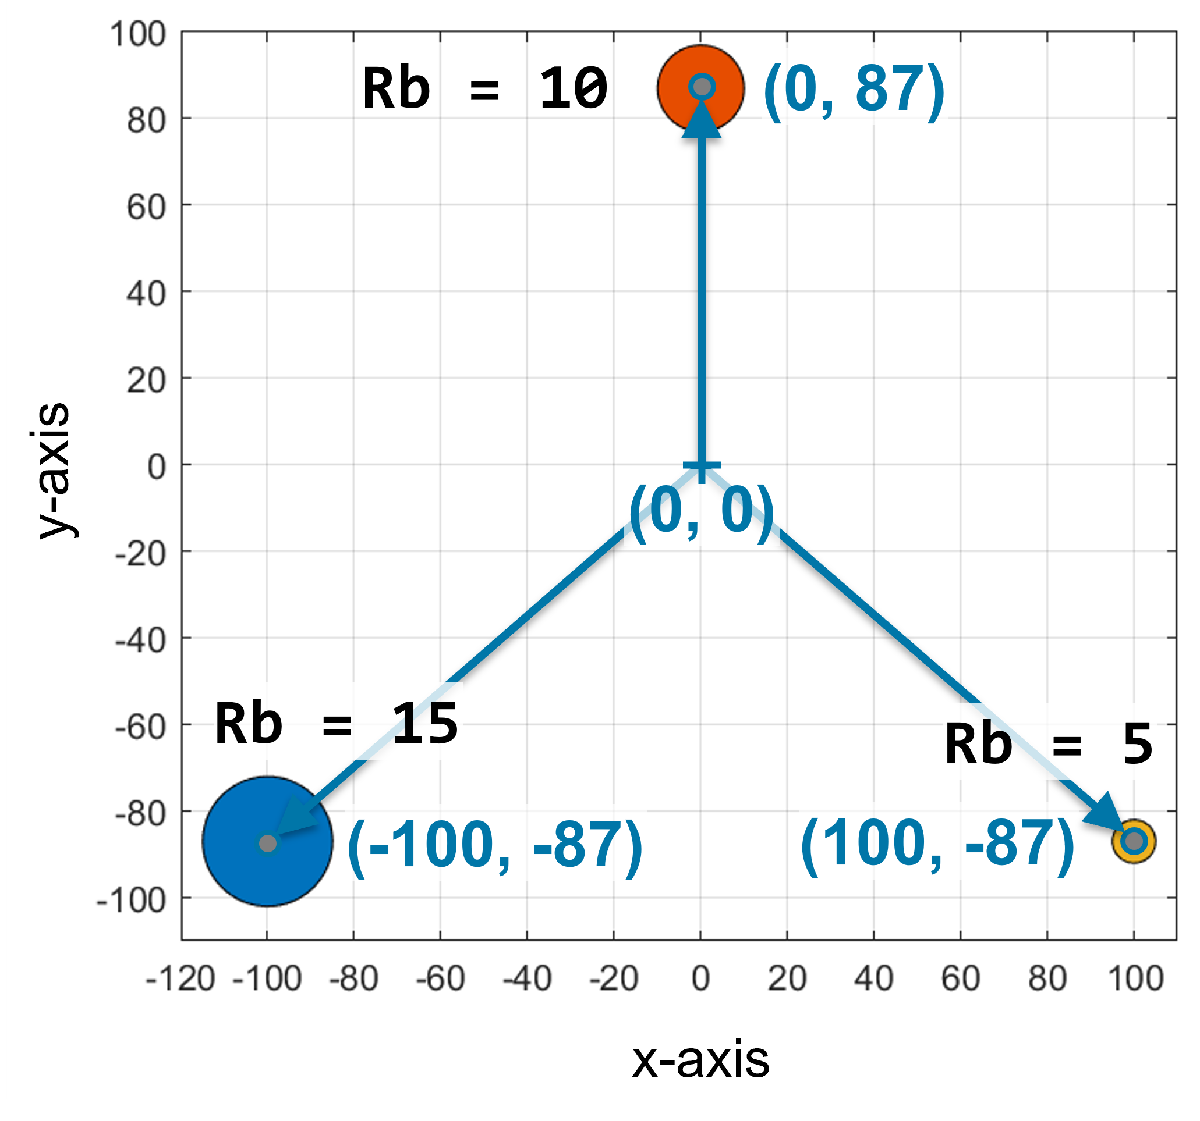

We'll define Body 1 to be the larger blue circle at the bottom left, Body 2 to be the medium red-orange circle at the top (already completed), and Body 3 to be the smaller yellow circle at the bottom right.

% TASK 5: All of the Body 1 and Body 3 values have been set to 0 below.
% Replace these zeros with values that match the x-location, y-location,
% size, and approximate color of these bodies illustrated above.
xb = [0  0 0];        % [body1 body2 body3] x-position
yb = [0 87 0];        % [body1 body2 body3] y-position
Rb = [0 10 0];        % [body1 body2 body3] size
cb = [  0  0  0; ...  % row 1: body1 color code
      217 83 25; ...  % row 2: body2 color code
        0  0  0]/255; % row 3: body3 color code

As you've seen above, by default MATLAB does not keep the previous plot in the new plot figure.  In order to display all bodies in the same figure, we'll need to command the axes to `hold` "on" to the previous plot.  The axes will then hold on to all future plots until commanded "off".

% Plot Body 1
cla(ax)  % clear axes
fill(ax,xb(1)+Rb(1)*xc,yb(1)+Rb(1)*yc,cb(1,:))
hold(ax,"on")

% TASK 6: Plot Body 2 by changing all of the 1 indices below to 2.
fill(ax,xb(1)+Rb(1)*xc,yb(1)+Rb(1)*yc,cb(1,:))

% TASK 7: Plot Body 3 by changing all of the 1 indices below to 3.
fill(ax,xb(1)+Rb(1)*xc,yb(1)+Rb(1)*yc,cb(1,:))
axis(ax,"equal")

## Better Way to Add Additional Bodies (Tasks 8, 9, & 10)

In the code above we used the first value of each array to plot Body 1; the second value of each array to plot Body 2; and the third value of each array to plot Body 3.  As such, notice we repeated almost the identical command 3 times, and only changed the index value to 1, 2, or 3, respectively.

Can you think of a better way to repeat this command `for` 3 times?  Hint, in general we're using a value of "k" to index into each array to plot Body k.

cla(ax)  % clear previous plots

% TASK 8: Change nb from 1 to the number of bodies we want to plot.
% Bonus: Use the length function with Rb to determine the number of bodies.
nb = 1;

% TASK 9: Currently the loop below is set for k = 1:1, 
% which means k only goes from 1 to 1 (in increments of 1).
% Change this so that the last value is the variable nb.
for k = 1:1
    
    % TASK 10: Plot each body by changing all of the 1 indices below to k.
    fill(ax,xb(1)+Rb(1)*xc,yb(1)+Rb(1)*yc,cb(1,:))

end
axis(ax,"equal")

## Final Solution (No Tasks)

Finally, let's consolidate all of our code into one section below.  However, this time we'll use a [colormap](https://www.mathworks.com/help/matlab/ref/colormap.html#buc3wsn-6) to specify the body colors instead of manually typing out all of the RGB color codes.  We can once again turn "on" the `grid`, and we'll also specify the desired display limits for the x and y axes.

ax = gca;  % get current axes
cla(ax)    % clear axes

% Body Parameters
xb = [-100 0  100];  % body x-positions
yb = [ -87 87 -87];  % body y-positions
Rb = [  15 10   5];  % body sizes
nb = length(Rb);     % number of bodies
cb = lines(nb);      % body colors (colormap)

% Points of a unit circle
ang = 0:5:360;       % angle, degrees
xc = cosd(ang);      % circle x-points
yc = sind(ang);      % circle y-points

% Plot Bodies 1 to 3
hold(ax,"on")
for k = 1:nb
    fill(ax,xb(k)+Rb(k)*xc,yb(k)+Rb(k)*yc,cb(k,:))
end
grid(ax,"on")
axis(ax,"equal")

% Set display limits (same as in PlotShips.mlx)
xlim(ax,[-300 300])  % x-axis limits [min max]
ylim(ax,[-200 200])  % y-axis limits [min max]

Copyright 2022 The MathWorks, Inc.